# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Sunday 22th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

%axis
axis = [1;1;2]

axis =      1
     1
     2


%angle
angle = 90

angle = 90

M = Eaa2rotMat(axis, angle)

M =     0.1667   -0.6498    0.7416
    0.9832    0.1667   -0.0749
   -0.0749    0.7416    0.6667


- Compare the transpose and the inverse of the resulting matrix

disp("Transpose")

Transpose


transM = transpose(M)

transM =     0.1667    0.9832   -0.0749
   -0.6498    0.1667    0.7416
    0.7416   -0.0749    0.6667


disp("Inverse")

Inverse


invM = inv(M)

invM =     0.1667    0.9832   -0.0749
   -0.6498    0.1667    0.7416
    0.7416   -0.0749    0.6667



subsM = transM - invM

subsM = 	1.0e+-15 *

    0.1110    0.5551    0.0694
         0    0.1110    0.3331
    0.3331    0.0555    0.3331


Both matrices are the same (subsM returns almost 0).

- Using the output matrix, transform a vector parallel to the axis of rotation. 

paralel_vec = [2;2;4]

paralel_vec =      2
     2
     4


rotated_vec = M*paralel_vec

rotated_vec =     2.0000
    2.0000
    4.0000


What happens?

    The vector remains the same after rotating it with a rotation  matrix created from a paralel vector.

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

perp_vec = [-5; 13; -4]

perp_vec =     -5
    13
    -4


rotated_vec = M*perp_vec

rotated_vec =   -12.2474
   -2.4495
    7.3485


 What you observe?

    It rotates the vector around the rotation matrix the specified angle around the specified  axis.

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5);

 contains 100 random (non-unit) axis. While 

theta = linspace(0,rad2deg(6*pi));

 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair theta-axis, (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

traces = zeros(1,100);

for num = 1:1:100
    M = Eaa2rotMat (axisM (:,num), theta(:,num));
    traces(1, num) = trace(M);
end

- Make a plot of the trace that you have obtained vs the theta angle. Explain what you observe.

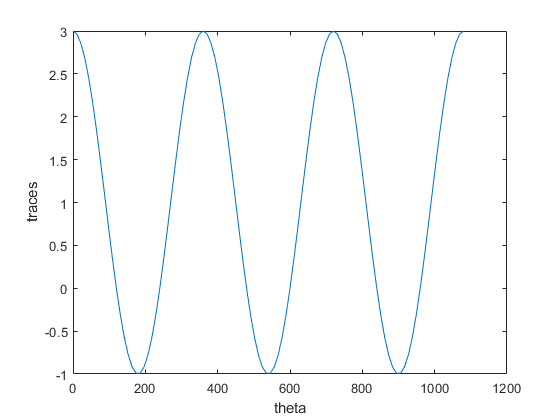

plot(theta, traces);
xlabel("theta");
ylabel("traces");

               * Explanation Here:*

*The plot shows us the relation of the trace and the angle of a rotation matrix.*

*The formula:*


$$\varphi =\mathrm{arccos}�\;\frac{\mathrm{trace}\left(R\right)-1}{2}$$


The relation we end up with is:


$$\mathrm{trace}\left(R\right)=2\;*\;\mathrm{cos}\left(\varphi \right)\;+\;1\;$$


Considering that the theta is the y axis and the traces are the x axis:


$$x=2\;*\;\cos \left(y\right)\;+\;1\;$$


## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

%axis
axis1 = [1;1;2]

axis1 =      1
     1
     2


%angle
angle1 = 90

angle1 = 90

M = Eaa2rotMat(axis1, angle1)

M =     0.1667   -0.6498    0.7416
    0.9832    0.1667   -0.0749
   -0.0749    0.7416    0.6667



[axis2, angle2] = rotMat2Eaa(M)

axis2 =     0.4082    0.4082    0.8165


angle2 = 90

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

r1 = [1, 0, 0; 0, 1, 0; 0, 0, 1]

r1 =      1     0     0
     0     1     0
     0     0     1


[axis1, angle1] = rotMat2Eaa(r1)

axis1 =    NaN   NaN   NaN


angle1 = 0

r2 = [-1/3, 2/3, 2/3; 2/3, -1/3, 2/3; 2/3, 2/3, -1/3]

r2 =    -0.3333    0.6667    0.6667
    0.6667   -0.3333    0.6667
    0.6667    0.6667   -0.3333


[axis2, angle2] = rotMat2Eaa(r2)

axis2 =    NaN   NaN   NaN


angle2 = 180

r3 = [0, 0, -1 ; 0 -1 0 ; -1 0 0]

r3 =      0     0    -1
     0    -1     0
    -1     0     0


[axis3, angle3] = rotMat2Eaa(r3)

axis3 =    NaN   NaN   NaN


angle3 = 180

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

r1 = [1, 0, 0; 0, 1, 0; 0, 0, 1]

r1 =      1     0     0
     0     1     0
     0     0     1


[axis1, angle1] = rotMat2Eaa2(r1)

axis1 =    NaN   NaN   NaN


angle1 = 0

r2 = [-1/3, 2/3, 2/3; 2/3, -1/3, 2/3; 2/3, 2/3, -1/3]

r2 =    -0.3333    0.6667    0.6667
    0.6667   -0.3333    0.6667
    0.6667    0.6667   -0.3333


[axis2, angle2] = rotMat2Eaa2(r2)

axis2 =    NaN   NaN   NaN


angle2 = 180

r3 = [0, 0, -1 ; 0 -1 0 ; -1 0 0]

r3 =      0     0    -1
     0    -1     0
    -1     0     0


[axis3, angle3] = rotMat2Eaa2(r3)

axis3 =    NaN   NaN   NaN


angle3 = 180

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


disp("Default");

Default


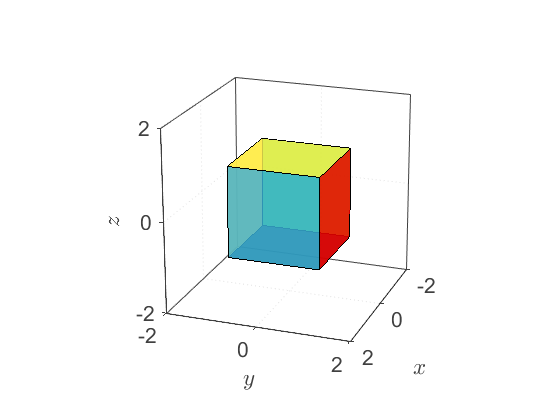

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);


disp("Cube A");

Cube A


axis = [0, 1, 0];
angle = 270;
rMat = Eaa2rotMat(axis, angle);
for num = 1:8
    M_mod(num, :) = M(num, :) * rMat;
end
rotVec = axis* deg2rad(angle);
disp(rotVec);

         0    4.7124         0



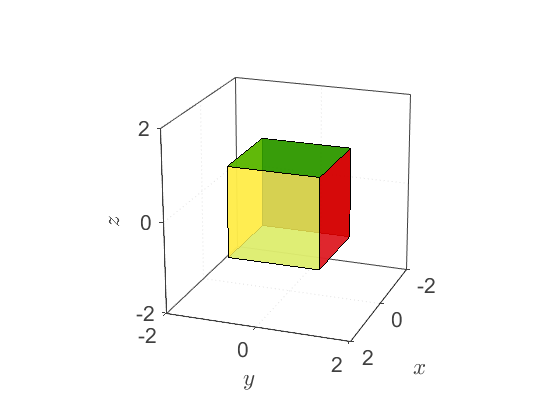

Cubeplot(M_mod);


disp("Cube B");

Cube B


axis = [1, 0, 0];
angle = -90;
rMat1 = Eaa2rotMat(axis, angle);
for num = 1:8
    M_mod(num, :) = M(num, :) * rMat1;
end
axis = [0, 0, 1];
angle = -90;
rMat2 = Eaa2rotMat(axis, angle);
for num = 1:8
    M_mod(num, :) = M_mod(num, :) * rMat2;
end
[axis, angle] = rotMat2Eaa(rMat2*rMat1);
rotVec = axis* deg2rad(angle);
disp(rotVec);

   -1.2092    1.2092   -1.2092



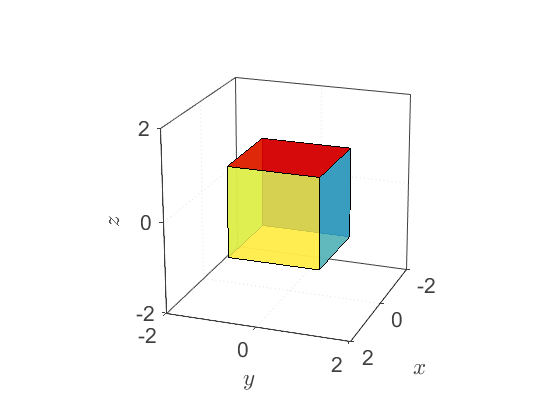

Cubeplot(M_mod);



disp("Cube C");

Cube C


axis = [0, 0, 1];
angle = -90;
rMat1 = Eaa2rotMat(axis, angle);
for num = 1:8
    M_mod(num, :) = M(num, :) * rMat1;
end

axis = [1, 0, 0];
angle = 180;
rMat2 = Eaa2rotMat(axis, angle);
for num = 1:8
    M_mod(num, :) = M_mod(num, :) * rMat2;
end
[axis, angle] = rotMat2Eaa(rMat2*rMat1);
rotVec = axis* deg2rad(angle);
disp(rotVec);

   NaN   NaN   NaN



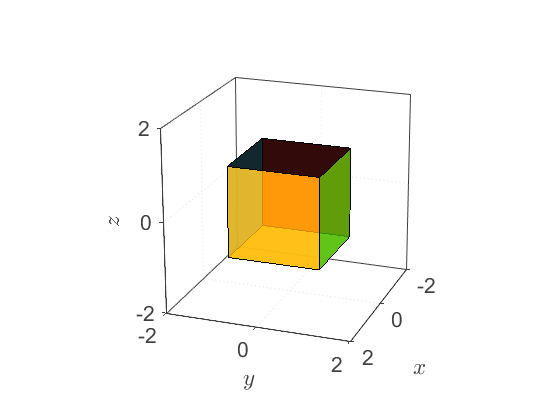

Cubeplot(M_mod);

Note: The last rotation vector is Nan Nan Nan because when we calculate the axis we divide by sin(angle) which in this case is 180º. That means it is going to divide by zero.

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

% Function test
vec = [1; 0; 0];
rMat = eAngles2rotM(90, 0 , 0);
vec = rMat * vec;

% Calculate the determinant
vec = [1; 1; 1];
rMat = eAngles2rotM(90, 90 , 90);
vec = rMat * vec;
determinant = det(rMat);

- Compare the transpose and the inverse of the resulting matrix

disp(transpose(rMat));

     0     0    -1
     0     1     0
     1     0     0



disp(inv(rMat));

     0     0    -1
     0     1     0
     1     0     0



**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented. You can set phi = 0 if you need it.

%See rotM2eAngles

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.

disp("Test 1 (flag = 0)");

Test 1 (flag = 0)


rMat = eAngles2rotM(60, 45 , 90);
disp("60, 45 , 90");

60, 45 , 90


[anglePhi, angleTheta, anglePsi, flag] = rotM2eAngles(rMat)

anglePhi =    60.0000 -120.0000


angleTheta =    45.0000  225.0000


anglePsi =     90   -90


flag = 0


disp("Test 2 (flag = 1)");

Test 2 (flag = 1)


rMat = eAngles2rotM(0, 90 , 0);
disp("0, 90 , 0");

0, 90 , 0


[anglePhi, angleTheta, anglePsi, flag] = rotM2eAngles(rMat)

anglePhi =      0     0


angleTheta =     90   270


anglePsi =      0   180


flag = 1


disp("Test 3 (flag = -1)");

Test 3 (flag = -1)


rMat = eAngles2rotM(0, 270 , 0);
disp("0, 270 , 0");

0, 270 , 0


[anglePhi, angleTheta, anglePsi, flag] = rotM2eAngles(rMat)

anglePhi =      0     0


angleTheta =    -90    90


anglePsi =      0   180


flag = -1